## mesh generation toolbox

### Author & support : nicolas.douillet (at) free.fr, 2020-2021.

### Example #1 : octahedron based geoid

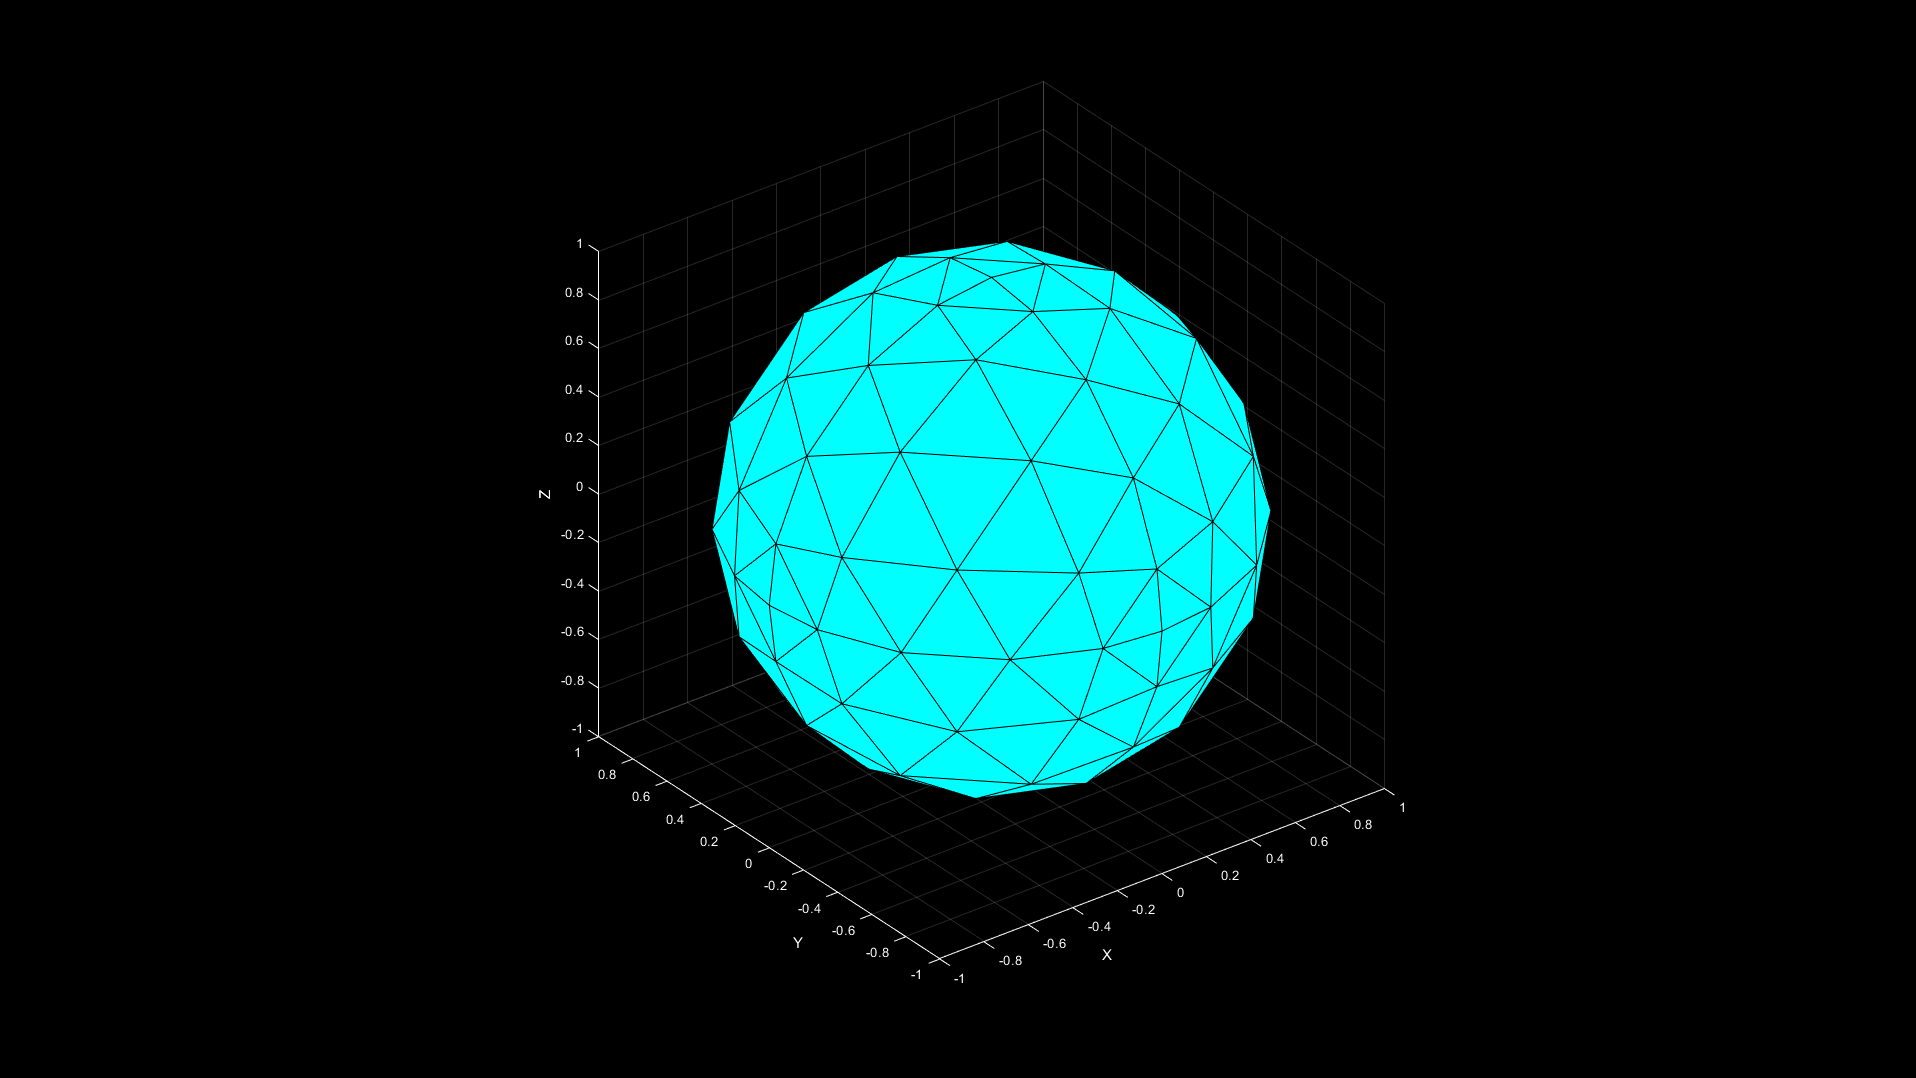

Mesh with 144 vertices and 200 triangles displayed in 3.294019e-01 seconds.


addpath('src/');
id = 3; % base = octahedron
nb_it = 5;
projection_mode = 'edge_oversamples';
[V,T] = build_geoid(id,projection_mode,nb_it);
plot_mesh(V,T);

### Example #2 : icosahedron based geoid

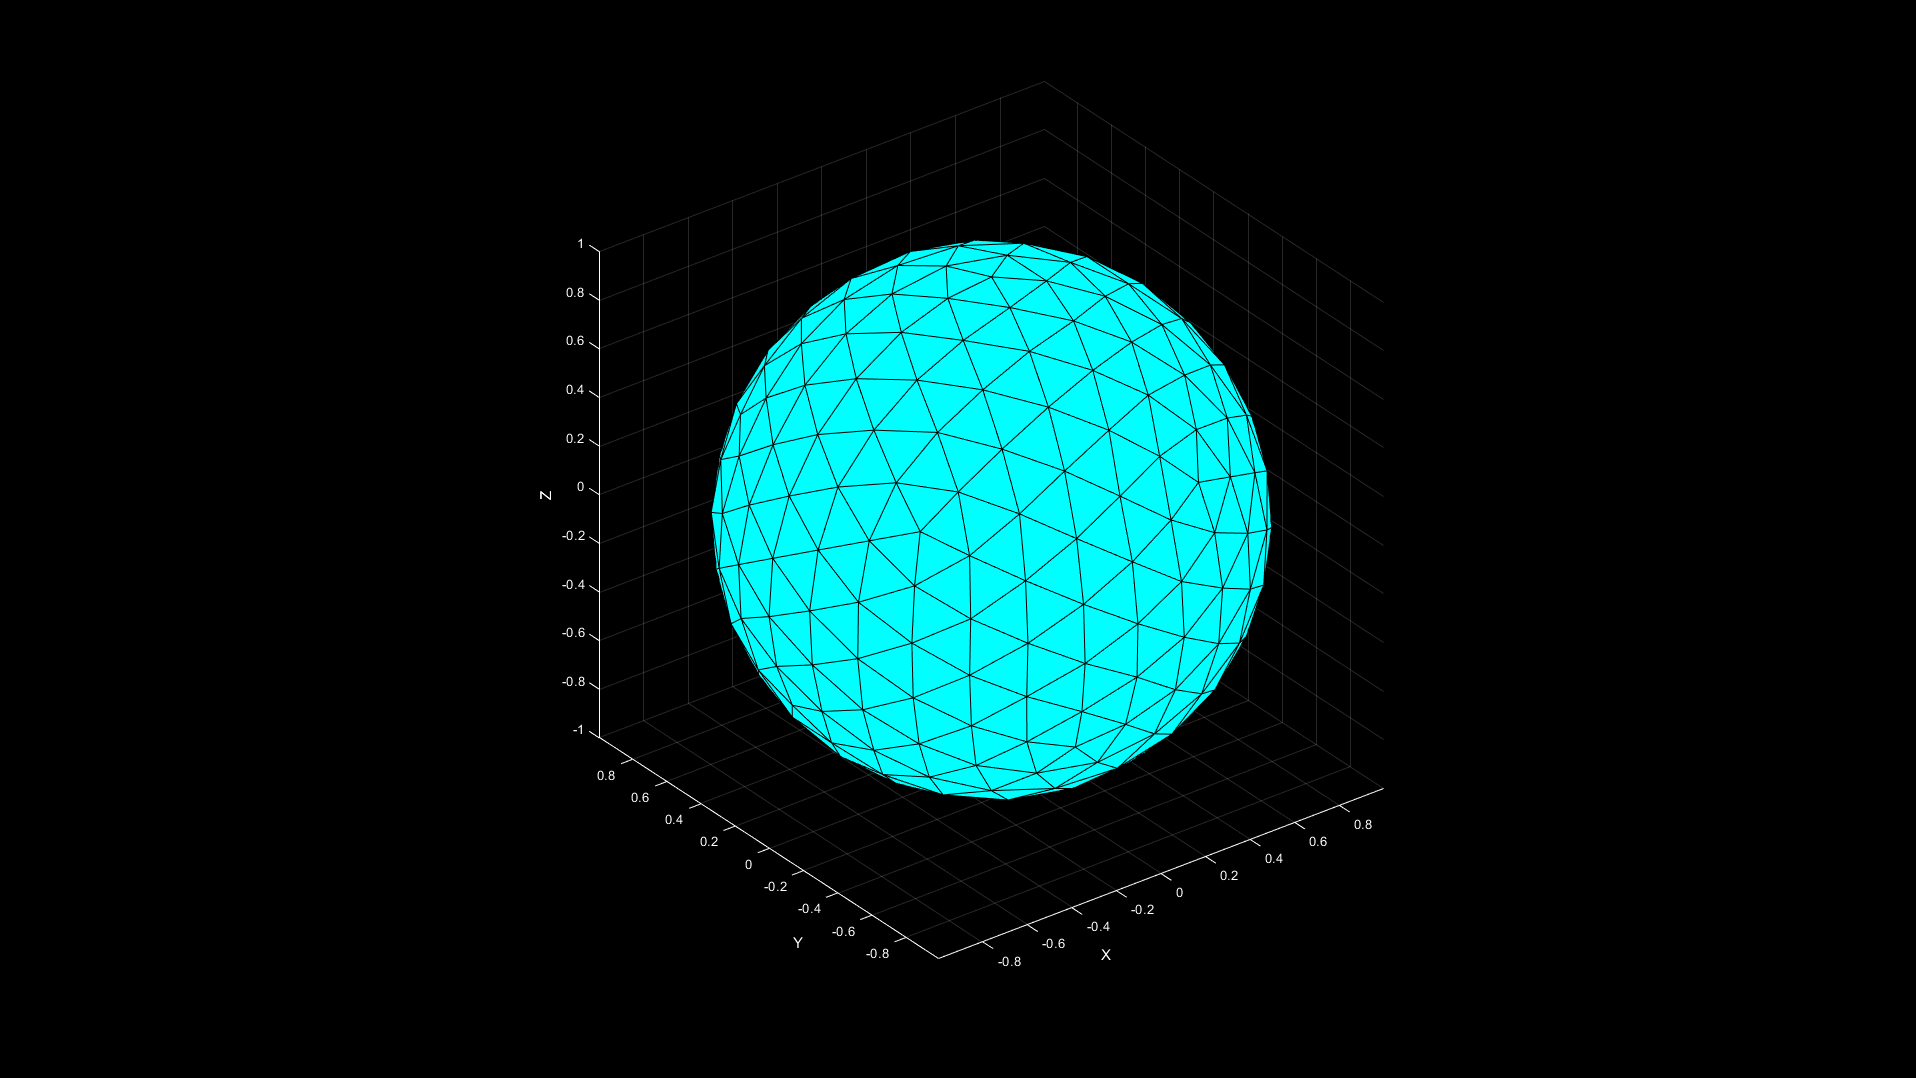

Mesh with 272 vertices and 540 triangles displayed in 1.326053e-01 seconds.


id = 4; % base = icosahedron
nb_it = 3;
projection_mode = 'face_centres';
[V,T] = build_geoid(id,projection_mode,nb_it);
plot_mesh(V,T);

### Example #3 : volumic mesh 

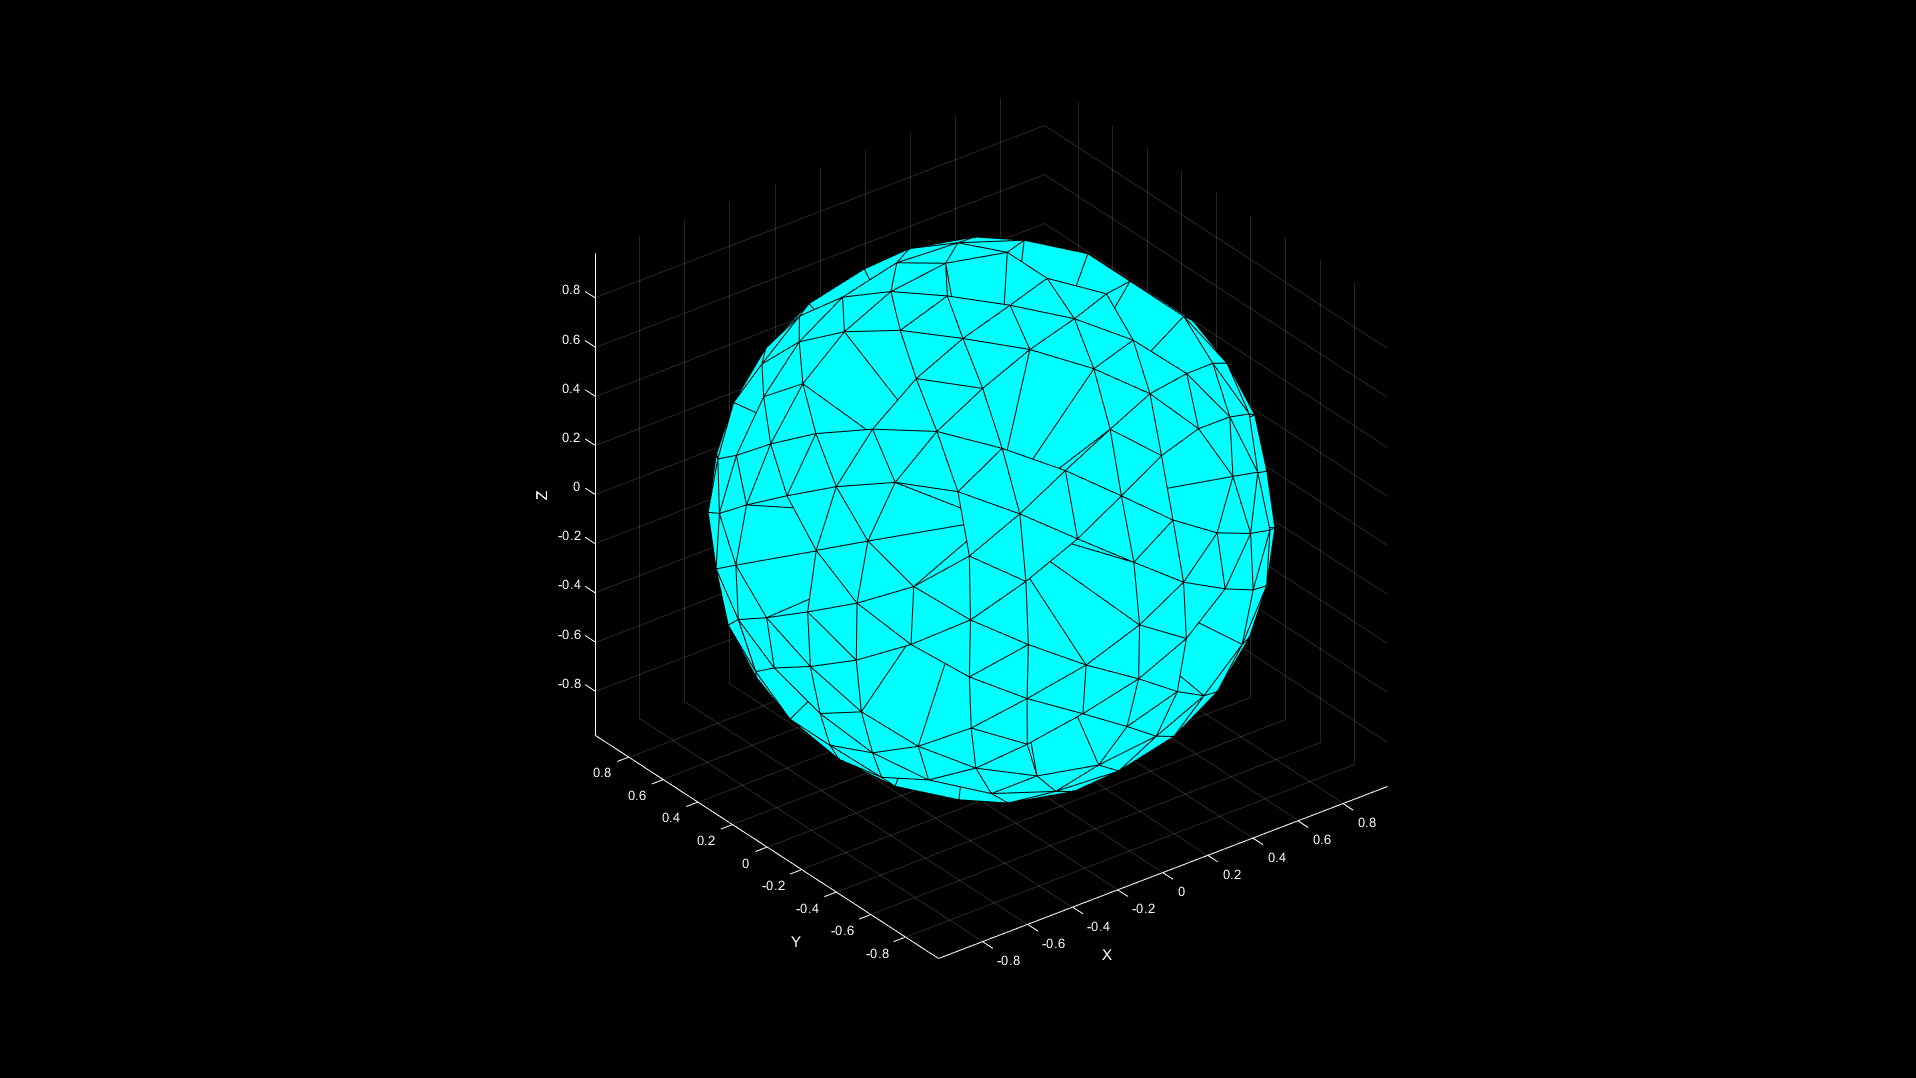

Mesh with 237 vertices and 942 triangles displayed in 1.160753e-01 seconds.


[V,T] = build_volumic_mesh_from_convex_set_mesh(V,T);
V_set = 1:36;
[V,T] = remove_vertices(V_set,V,T); % remove some vertices to have an insight view
plot_mesh(V,T);

### Example #4 : discrete contour mesh patch

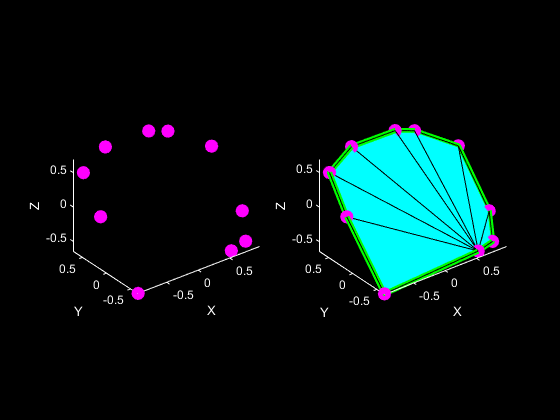

n = 32;
V = 2*(rand(n,2)-0.5);
H_raw = convhull(V);

if size(V,2) == 2 
    V = cat(2,V,zeros(size(V,1),1));        
end

Rmx = @(theta)[1 0          0;
               0 cos(theta) -sin(theta);
               0 sin(theta) cos(theta)];

V = (Rmx(0.25*pi)*V')';
V = V(unique(H_raw,'stable'),:);
V = V([end,end-1,1,2:end-2],:); % disorder ( = V_in)

[C,T,N] = discrete_contour_mesh_patch(V);

h = figure;
% set(h,'Position',get(0,'ScreenSize'));
set(gcf,'Color',[0 0 0]);

subplot(121);
plot3(C(:,1),C(:,2),C(:,3),'bo','LineWidth',4,'MarkerSize',6,'MarkerFaceColor', [1 0 1],'MarkerEdgeColor', [1 0 1]), hold on;
xlabel('X'), ylabel('Y'), zlabel('Z');
axis equal, axis tight;
set(gca, 'Color', [0 0 0], 'XColor', [1 1 1], 'YColor', [1 1 1], 'ZColor', [1 1 1]);
view(3);

subplot(122);
plot3(C(:,1),C(:,2),C(:,3),'bo','LineWidth',4,'MarkerSize',6,'MarkerFaceColor', [1 0 1],'MarkerEdgeColor', [1 0 1]), hold on;
line(cat(1,C(:,1),C(1,1)),cat(1,C(:,2),C(1,2)),cat(1,C(:,3),C(1,3)),'Color',[0 1 0],'LineWidth',4), hold on;
trisurf(T,C(:,1),C(:,2),C(:,3)), shading faceted, hold on;
colormap([0 1 1]);        

xlabel('X'), ylabel('Y'), zlabel('Z');
axis equal, axis tight;
ax = gca;
ax.Clipping = 'off';
set(ax, 'Color', [0 0 0], 'XColor', [1 1 1], 'YColor', [1 1 1], 'ZColor', [1 1 1]);
view(3);